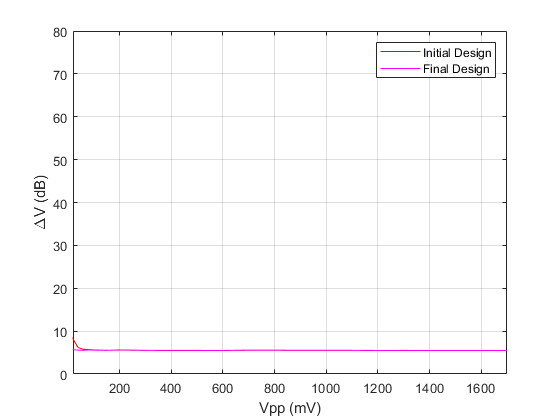

close all
snrFiles1 = dir(fullfile('C:\Users\jhend_000\Documents\MATLAB\SNR_varyin_FINALDESIGN', '*.WAV'));
snrFiles2 = dir(fullfile('C:\Users\jhend_000\Documents\MATLAB\Test_A', '*.WAV'));

my_snrFiles1 = natsortfiles({snrFiles1.name});
my_snrFiles2 = natsortfiles({snrFiles2.name});

rmsOut1 = zeros(1,25);
rmsOut2 = zeros(1,25);
rmsRatio1 = zeros(1,25);
rmsRatio2 = zeros(1,25);
SNR1 = zeros(1,25);
SNR2 = zeros(1,25);

rmsT1 = zeros(1,25);
rmsTrueNoise1 = zeros(1,25);
rmsTrueNoise2 = zeros(1,25);
x1 = [4 8 20 40 60 80 100 150 200 250 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700];
mySnr1 = zeros(1,25);
mySnr2 = zeros(1,25);
SNRDiff = zeros(1,25);

for i = 1:25
    
    [myOutRead1, FS1] = audioread(my_snrFiles1{i});
    [myOutRead2, FS2] = audioread(my_snrFiles2{i});
    
    rmsT1(i) = ((x1(i)/2)*0.7071)/1000;
    rmsOut1(i) = rms(myOutRead1);
    rmsOut2(i) = rms(myOutRead2);
    
    rmsTrueNoise1(i) = abs(rmsT1(i) - rmsOut1(i)); 
    rmsTrueNoise2(i) = abs(rmsT1(i) - rmsOut2(i)); 
    
    SNR1(i) = 20*log10(rmsOut1(i)/rmsTrueNoise1(i)); 
    SNR2(i) = 20*log10(rmsOut2(i)/rmsTrueNoise2(i));
    
    mySnr1(i) = snr(myOutRead1, FS1);
    mySnr2(i) = snr(myOutRead2, FS2);
    rmsRatio1(i) = rmsT1(i)/rmsOut1(i);
    rmsRatio2(i) = rmsT1(i)/rmsOut2(i);
    
    SNRDiff(i) = mySnr1(i) - mySnr2(i);
end

figure
plot(x1,SNR2, 'r');
xlabel('Vpp')
ylabel('dB')
grid on
hold on

plot(x1,SNR1 , 'm');
xlabel('Vpp (mV)')
ylabel('{\Delta}V (dB)')
xlim([20 1700])
ylim([0 80])
%title('Difference between Input and Output Voltage Versus Peak-To-Peak Voltage Comparisson Between Initial and Final Designs')
grid on

legend('Initial Design','Final Design')
hold on

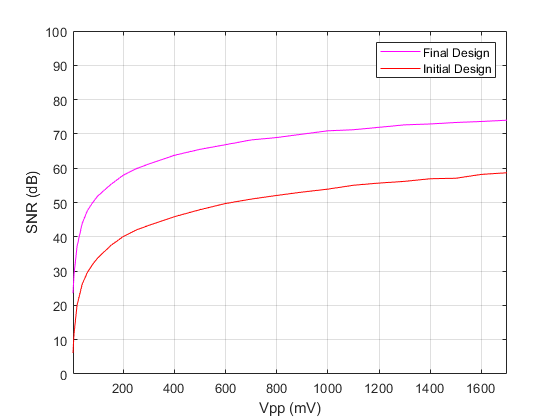


figure
plot(x1,mySnr1, 'm');
xlabel('Vpp (mV)')
ylabel('SNR (dB)')
xlim([4 1700])
ylim([0 100])
grid on

hold on 

plot(x1,mySnr2, 'r');
xlabel('Vpp (mV)')
ylabel('SNR (dB)')
%title('SNR Versus Peak-To-Peak Voltage Comparisson Between Initial And Final Designs')
grid on
legend('Final Design', 'Initial Design')

hold on 